# Task 1

disp("Task 1")

Task 1


f1 = @(x) (sin(x)-(x.^3).*cos(x));

f1 = function_handle with value:
    @(x)(sin(x)-(x.^3).*cos(x))


quad(f1, -4, 0, 1.0e-05)

ans = -53.3788

## Task 2

disp("Task 2")

Task 2


f2 = @(x) (x.^3+1);
integral(f2, 2, 5)

ans = 155.2500

## Task 3

disp("Task 3")

Task 3


f3 = @(x,y)(exp(-x).*sin(y));
dblquad(f3, -pi, pi, 0, 3)

ans = 45.9638

integral2(f3, -pi, pi, 0, 3)

ans = 45.9638

## Task 4

disp("Task 4")

Task 4


figure;
z = @(x, y) (sin(x).*sin(y).*(1-x.^2).*x.*(1-y));
integral2(z, -2, 2, -2, 2)

ans = 14.2783

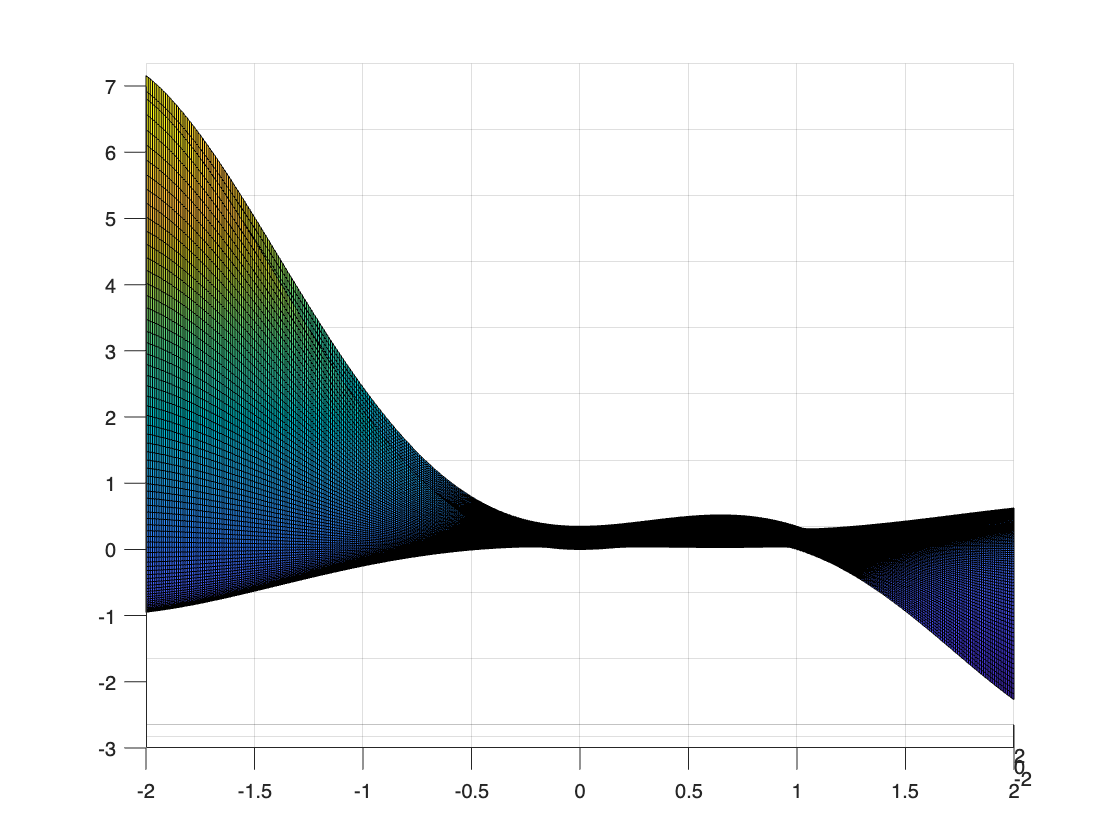

[X, Y] = meshgrid(-2:0.01:2);
Z = (sin(X).*cos(Y).*(1-Y.^2).*X.*(1-X));
surf(X, Y, Z)
view(0,2)

## Task 5

disp("Task 5")

Task 5


f5 = @(x,y,z) (exp(-x).*sin(y).*cos(z));
triplequad(f5, -pi, pi, -2*pi, pi, 0, 2)

ans = 42.0050

integral3(f5, -pi, pi, -2*pi, pi, 0, 2)

ans = 42.0050

## Task 6

disp("Task 6")

Task 6


f6 = @(x,y,z) (exp(x).*(sin(y)).^2+exp(-x).*(cos(y)).^2+sin(y).*cos(x).*z);
integral3(f6, -2*pi, 2*pi, -2*pi, 2*pi, -1, 1)

ans = 1.3458e+04

## Task 7

disp("Task 7")

Task 7


f7 = @(x) (1./x);
quad(f7, 0, 1)

ans = 45.8263

quadl(f7, 0, 1)

ans = 43.7383

quadgk(f7, 0, 1)

ans = Inf

## Task 8

disp("Task 8")

Task 8


a = 20;
b = 7;
f8 = @(x,y)((a.*cos(x).*(x.^2)+b.*sin(y).*(y.^2)));
integral2(f8,-2,2,-2,2)

ans = 24.6412

## Task 9

disp("Task 9")

Task 9


f9 = inline('a*(x.^2)+x+1','x', 'a');
a = 3;
quad(f9, 0, 10, 1.0e-05, 1, a)

       9     0.0000000000     2.71580000e+00    26.4341568483
      11     2.7158000000     4.56840000e+00   393.8763451434
      13     7.2842000000     2.71580000e+00   639.6894980083


ans = 1060

## Task 10

disp("Task 10")

Task 10


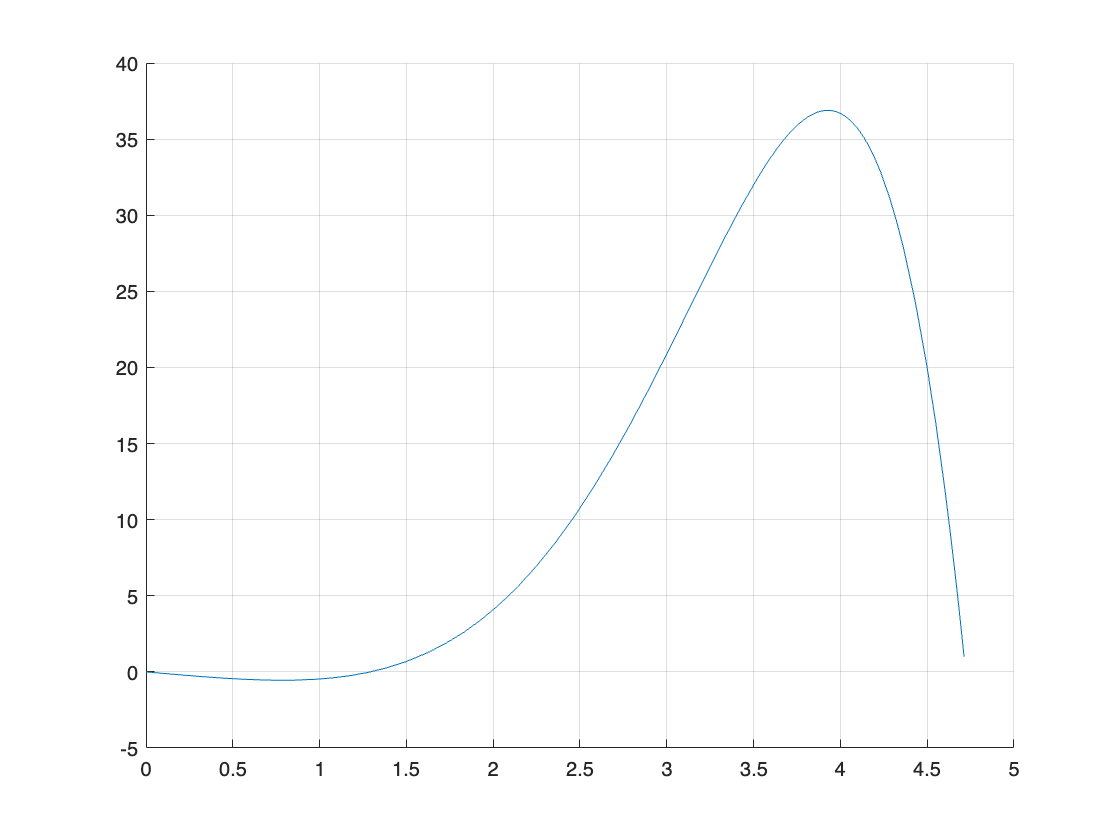

f10 = @(y) (quad(@(x)(exp(x).*(sin(x)-cos(x))), 0, y, 1.0e-09));
figure;
hold on;
grid on;
fplot(f10, [0,1.5*pi])

## Task 11

disp("Task 11")

Task 11


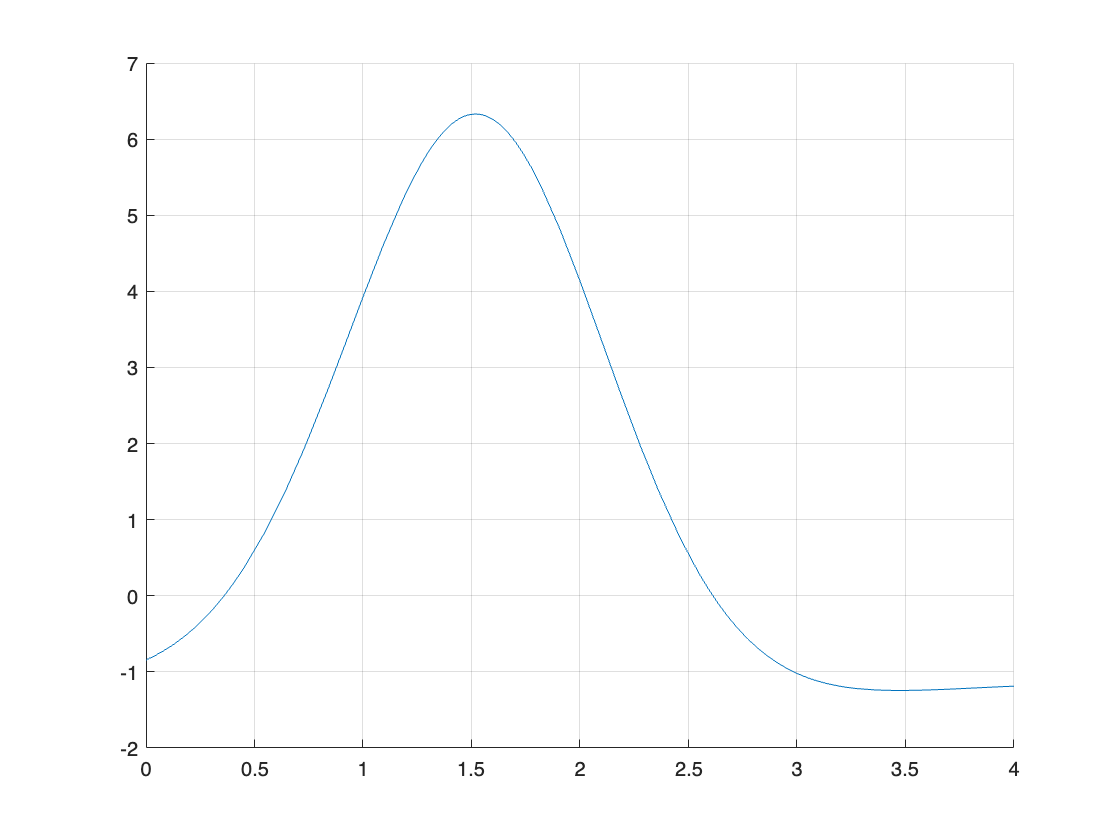

figure;
grid on;
hold on;
f11 = @(x) (cos(x-sqrt(2)).*exp(2.*sin(x))-1);
fplot(f11, [0 4]) 

x1 = fzero(f11, 1);
x2 = fzero(f11, 3);
integral(f11, x1, x2)

ans = 7.7598

## Task 12

disp("Task 12")

Task 12


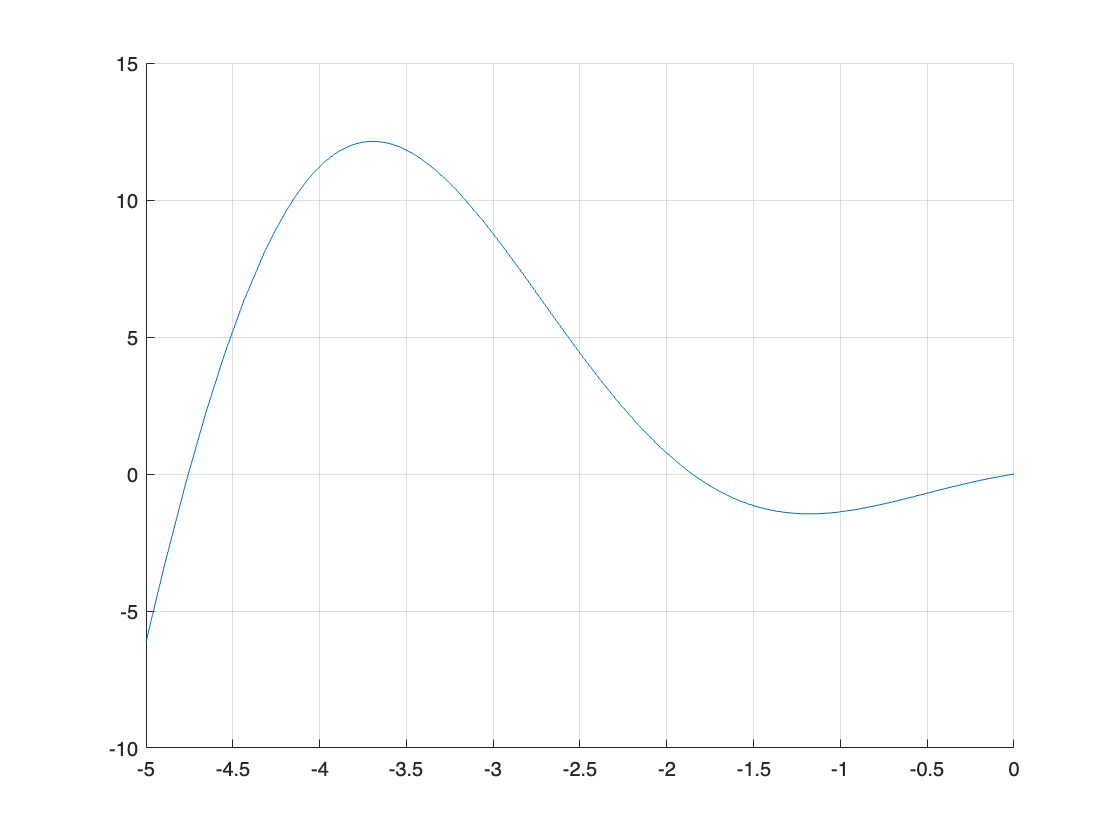

figure;
grid on;
hold on;
f12 = @(x) (sin(x)-(x.^2).*(cos(x)));

fplot(f12, [-5 0]) 


locmin = fminbnd(f12, -2, 0) 

locmin = -1.1785


f12max = @(x) ((sin(x)-(x.^2).*(cos(x))) .* -1); 
locmax = fminbnd(f12max, -5, -3.5) 

locmax = -3.6929


integral(f12, locmax, locmin)

ans = 11.4896